# Motor Drive Unit - Simulation Case

## Randomly generated input signals

Test that the model runs with reasonably random inputs. This is part of stress-test.

mdl = "MotorDriveUnit_harness_model";
load_system(mdl)
MotorDriveUnit_harness_setup

Select model to use.

MotorDriveUnit_useRefsub_BasicThermal

Model: MotorDriveUnit_harness_model
Setting up referenced subsystem: MotorDriveUnit_refsub_BasicThermal


Load simulation case.

MotorDriveUnit_setSimCase_Random

Setting up simulation...
Simulation case: Randomly generated input signals
Setting simulation stop time to 317 sec.
Setting block parameters...
batteryHV.nominalVoltage_V = 340
batteryHV.internalResistance_Ohm = 0.01
Setting initial conditions...
initial.loadInertiaSpd_rpm = 0
initial.motorSpd_rpm = 0
initial.motorDriveUnit_Temperature_K = 293.15
initial.ambientTemp_K = 293.15


Run simulation.

simOut = sim(mdl);

Visually inspect the result.

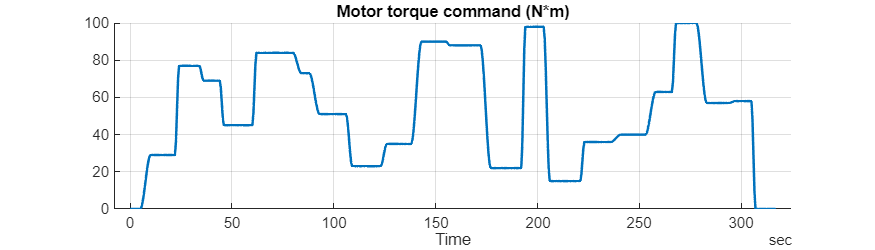

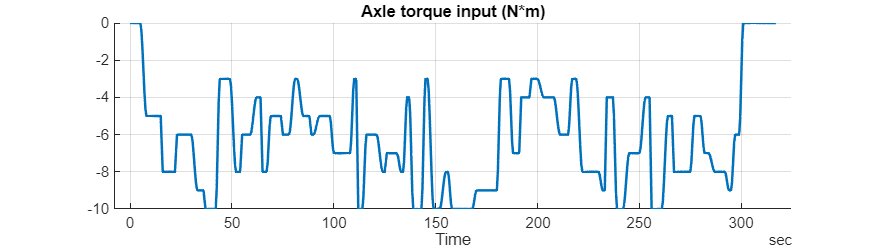

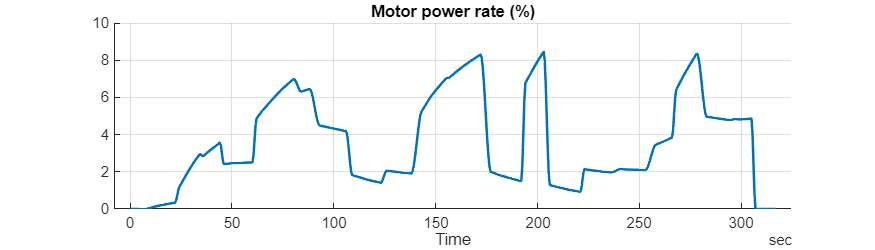

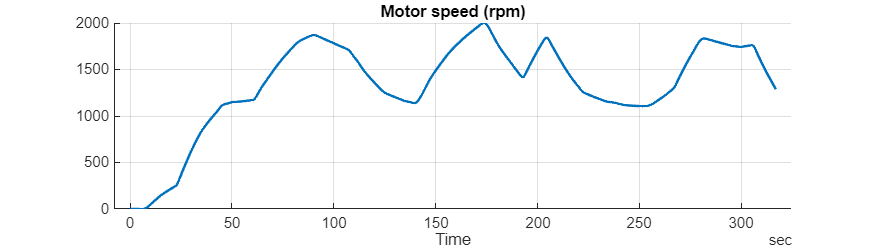

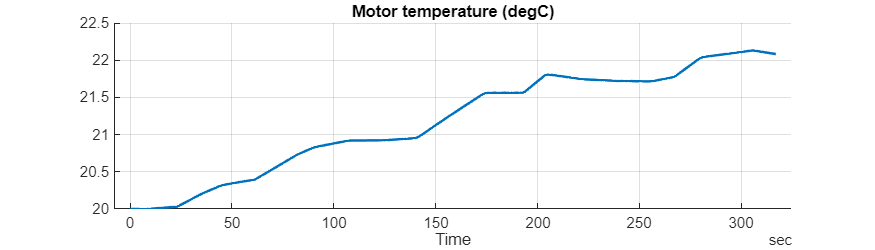

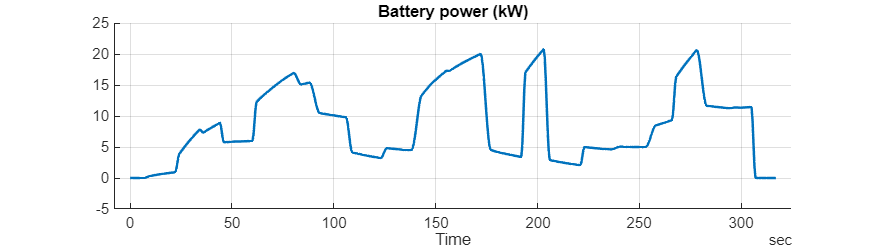

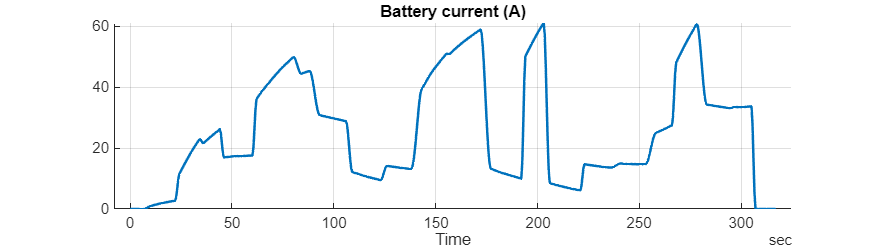

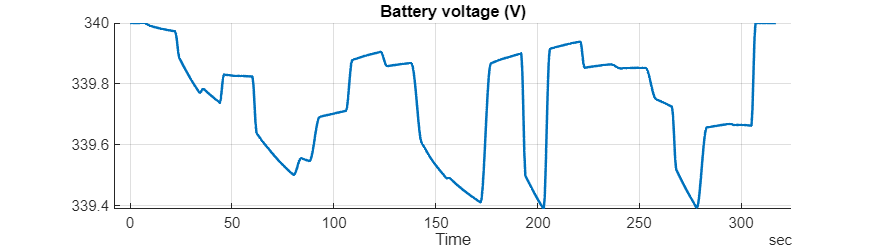

simData = extractTimetable(simOut.logsout);
sigNames = [
  "Motor torque command"
  "Axle torque input"
  "Motor power rate"
  "Motor speed"
  "Motor temperature"
  "Battery power"
  "Battery current"
  "Battery voltage"
  ];
for i = 1 : numel(sigNames)
  TimetableSingleSignalPlot( ...
    Timetable = simData, ...
    SignalName = sigNames(i), ...
    PlotHeight = 200 );
end

*Copyright 2021-2025 The Mathworks, Inc.*